# Projecting Shadows:  Examples

This library contains utilities for exploring shadows.  These examples show how to cast a shadow from a triangualtion.

To cast a shadow from a triangulation, we first need a shape that will cast a shadow.

This code snippet first creates a triangulation of a wavy donut shape, then uses the `triMeshShadow` utility to draw it.  When no inputs are provided to triMeshShadow, it computes necessary other inputs to provide a reasonable picture.

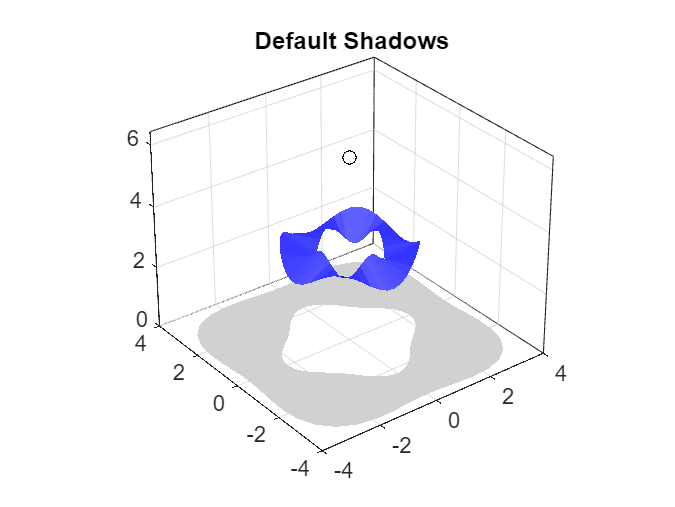

sz=50;
t=linspace(0,2,sz)';
x=cospi(t);
y=sinpi(t);
z=cospi(t*4)/3;

tri = triangulation([ 1:sz; 2:sz 1; [2:sz 1]+sz; (1:sz)+sz ]',...
                    [x y z+3; x*2 y*2 -z+3]);

triMeshShadow(tri);
title('Default Shadows')

You can also specify where you'd like the light object to be.

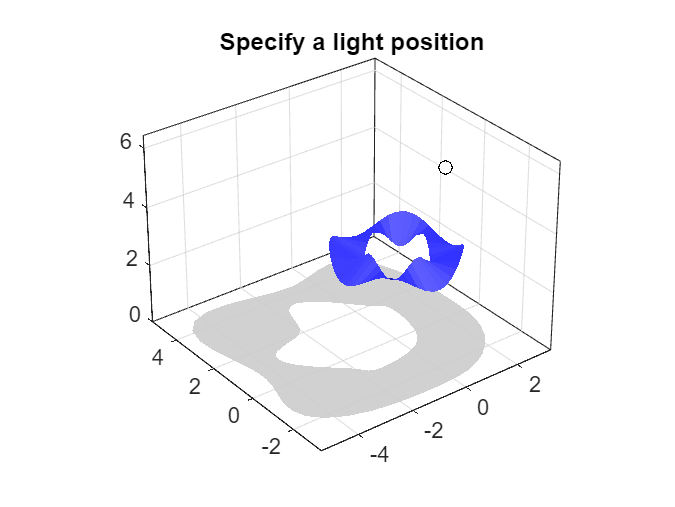

lightpos = [ 1 -1 6 ];
triMeshShadow(tri, lightpos);
title('Specify a light position');

Alternately, you can compute the data for the triangulation, and pass that into `triMeshShadow`.  `tri2shadow` will return both the shadow triangulation, and `FaceVertexAlphaData` needed to attenuation the shadow.

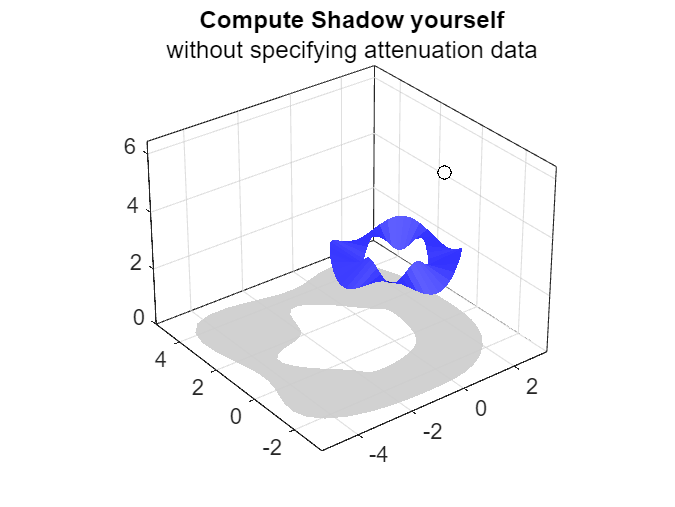

[shadow, fva] = tri2shadow(tri, lightpos);

% No attenuation
triMeshShadow(tri, lightpos, 'ShadowTri', shadow);
title('Compute Shadow yourself','without specifying attenuation data');

Lastly, you can also pass in the attenuation data to soften the farther extents of the shaodw.

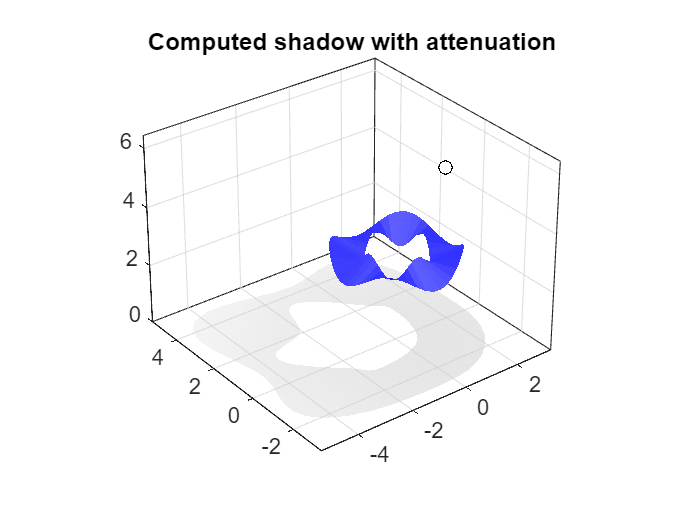

triMeshShadow(tri, lightpos, 'ShadowTri', shadow, 'ShadowFVA', fva);
title('Computed shadow with attenuation')

*Copyright 2024 The MathWorks, Inc.*